### Assumptions:

    1. Small angles: $\sin \left(\theta \;\right)=\theta \;$

clear all
k = [100,100,100,100];
c = [0,0,0,0];


syms m1 m2 m3 I1 % mass 1,2,3 & inertia for M1
syms k1 k2 k3 k4 % spring constants
syms c1 c2 c3 c4 % damping constants
syms L1 L2 %distance of point A & B to the centre of M1
 syms k0 % tortinal spring constant


syms x1 x1_dot x1_ddot % displacement, velocity & acceleration of M1
syms x2 x2_dot x2_ddot % displacement, velocity & acceleration of M2
syms x3 x3_dot x3_ddot % displacement, velocity & acceleration of M3

syms theta theta_dot theta_ddot % angluar displacement, velocity & acceleration of M1





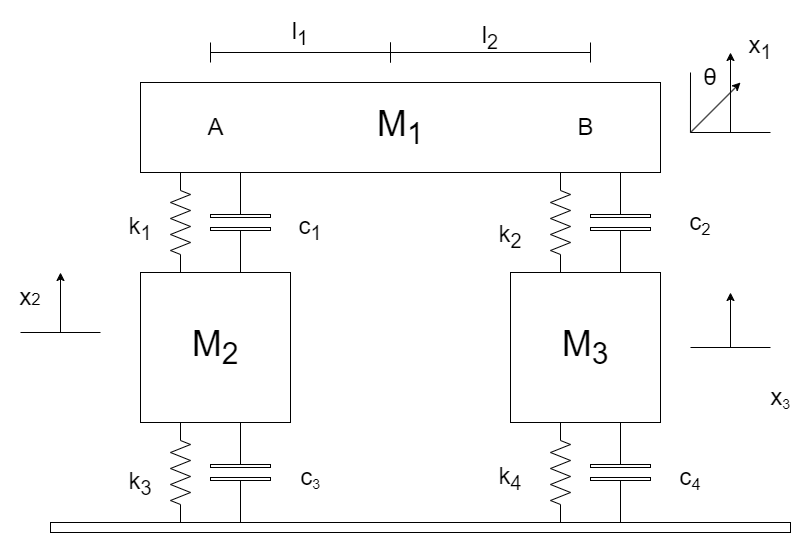

F_A = k1*(x1-x2-L1*theta)+c1*(x1_dot -x2_dot-L1*theta_dot) - k0 *(theta)/L1
F_B = k2*(x1-x3+L2*theta)+c2*(x1_dot -x3_dot+L2*theta_dot) + k0 *(theta)/L2

F2 =k3*(x2) + c3*(x2_dot)
F3 = k4*(x3) + c4*(x3_dot)

Create Equations based on these forces & newtons 2nd law

EQ_2 = m2*x2_ddot == F_A - F2
EQ_3 = m3*x3_ddot == F_B - F3


EQ_1 = m1 * x1_ddot == -(F_A + F_B)

Create the equation for the roll of the rig

EQ_1_Roll = I1 * theta_ddot == F_A*L1-F_B*L2




System_EQ = [EQ_1;
             EQ_1_Roll;
             EQ_2;
             EQ_3]
matrix_format = [x1_ddot, theta_ddot,x2_ddot,x3_ddot,...
                 x1_dot, theta_dot, x2_dot, x3_dot,...
                 x1,     theta,      x2,     x3;]

[A,F_Mat] = equationsToMatrix(System_EQ,matrix_format)
M_Mat = A(:,1:4)
C_Mat = A(:,5:8)
K_Mat = A(:,9:12)





### Creating Simulink Model for SImulated solution

% MODEL="Simulink_4DOF_Model"
% if(4==exist(MODEL))
%     close_system(MODEL,0);
%     delete(MODEL);
% end
% new_system(MODEL)
% open_system(MODEL)
%  matlabFunctionBlock( [MODEL+'/my_M_mat'], M_Mat);
%     matlabFunctionBlock( [MODEL+'/my_C_mat'], C_Mat);    
%     matlabFunctionBlock( [MODEL+'/my_K_mat'], K_Mat);   
%     matlabFunctionBlock( [MODEL+'/my_F_col'], F_Mat);
% 
% purple_str = '[0.6, 0.6, 1]';
%     set_param([MODEL+'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
%     set_param([MODEL+'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
%     set_param([MODEL+'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
%     set_param([MODEL+'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    
% 
% 












### Modal Analysis

Start off by putting actual values into all the symbolic variables

sym_list = [ m1, m2, m3, I1,...
k1, k2, k3, k4,...
c1, c2, c3, c4,...
L1, L2, k0];
value_list = zeros(size(sym_list));

test = readtable("car_rig_data.xlsx")
for i=1:size(value_list,2)
    value_list(1,i) = test.Var2(i);
end

M_matrix_raw = double(subs(M_Mat,sym_list,value_list))
C_matrix_raw = double(subs(C_Mat,sym_list,value_list))
K_matrix_raw = double(subs(K_Mat,sym_list,value_list))


A = inv(M_matrix_raw)*K_matrix_raw;
[eigenVector, eigenValues] = eig(A);
[~,ind] = sort(diag(eigenValues));

eigenVector=eigenVector(:,ind);
eigenValues=eigenValues(:,ind);
wn=[4];
for i=1:size(eigenValues,1)
%    vec(:,i) = vec(:,i)/max(abs(eigenVector(:,i)));
   wn(i) = sqrt(abs(sort(eigenValues(i,i))));
    
end

Testing normalisation of data. I don't really see the use.

$$F\_A = -c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)-\frac{k_{0}\,\theta }{L_{1}}$$

$$F\_B = c_{2}\,\left(x_{\dot{1}}-x_{\dot{3}}+L_{2}\,\dot{\theta }\right)+k_{2}\,\left(x_{1}-x_{3}+L_{2}\,\theta \right)+\frac{k_{0}\,\theta }{L_{2}}$$

$$F2 = c_{3}\,x_{\dot{2}}+k_{3}\,x_{2}$$

$$F3 = c_{4}\,x_{\dot{3}}+k_{4}\,x_{3}$$

$$EQ\_2 = m_{2}\,x_{\ddot{2}}=-c_{3}\,x_{\dot{2}}-k_{3}\,x_{2}-c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)-\frac{k_{0}\,\theta }{L_{1}}$$

$$EQ\_3 = m_{3}\,x_{\ddot{3}}=c_{2}\,\left(x_{\dot{1}}-x_{\dot{3}}+L_{2}\,\dot{\theta }\right)-k_{4}\,x_{3}-c_{4}\,x_{\dot{3}}+k_{2}\,\left(x_{1}-x_{3}+L_{2}\,\theta \right)+\frac{k_{0}\,\theta }{L_{2}}$$

$$EQ\_1 = m_{1}\,x_{\ddot{1}}=c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)-c_{2}\,\left(x_{\dot{1}}-x_{\dot{3}}+L_{2}\,\dot{\theta }\right)+k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)-k_{2}\,\left(x_{1}-x_{3}+L_{2}\,\theta \right)+\frac{k_{0}\,\theta }{L_{1}}-\frac{k_{0}\,\theta }{L_{2}}$$

$$EQ\_1\_Roll = I_{1}\,\ddot{\theta }=-L_{1}\,\left(c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)+k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right)+\frac{k_{0}\,\theta }{L_{1}}\right)-L_{2}\,\left(c_{2}\,\left(x_{\dot{1}}-x_{\dot{3}}+L_{2}\,\dot{\theta }\right)+k_{2}\,\left(x_{1}-x_{3}+L_{2}\,\theta \right)+\frac{k_{0}\,\theta }{L_{2}}\right)$$

$$System\_EQ = \begin{array}{l} \left(\begin{array}{c} m_{1}\,x_{\ddot{1}}=\sigma_{2}-\sigma_{1}+\sigma_{4}-\sigma_{3}+\frac{k_{0}\,\theta }{L_{1}}-\frac{k_{0}\,\theta }{L_{2}}\\ I_{1}\,\ddot{\theta }=-L_{1}\,\left(\sigma_{2}+\sigma_{4}+\frac{k_{0}\,\theta }{L_{1}}\right)-L_{2}\,\left(\sigma_{1}+\sigma_{3}+\frac{k_{0}\,\theta }{L_{2}}\right)\\ m_{2}\,x_{\ddot{2}}=-c_{3}\,x_{\dot{2}}-k_{3}\,x_{2}-\sigma_{2}-\sigma_{4}-\frac{k_{0}\,\theta }{L_{1}}\\ m_{3}\,x_{\ddot{3}}=\sigma_{1}-k_{4}\,x_{3}-c_{4}\,x_{\dot{3}}+\sigma_{3}+\frac{k_{0}\,\theta }{L_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{2}\,\left(x_{\dot{1}}-x_{\dot{3}}+L_{2}\,\dot{\theta }\right)\\ \sigma_{2}=c_{1}\,\left(x_{\dot{2}}-x_{\dot{1}}+L_{1}\,\dot{\theta }\right)\\ \sigma_{3}=k_{2}\,\left(x_{1}-x_{3}+L_{2}\,\theta \right)\\ \sigma_{4}=k_{1}\,\left(x_{2}-x_{1}+L_{1}\,\theta \right) \end{array}$$

$$matrix\_format = \left(\begin{array}{cccccccccccc} x_{\ddot{1}} & \ddot{\theta } & x_{\ddot{2}} & x_{\ddot{3}} & x_{\dot{1}} & \dot{\theta } & x_{\dot{2}} & x_{\dot{3}} & x_{1} & \theta & x_{2} & x_{3} \end{array}\right)$$

$$A = \begin{array}{l} \left(\begin{array}{cccccccccccc} m_{1} & 0 & 0 & 0 & c_{1}+c_{2} & \sigma_{2} & -c_{1} & -c_{2} & k_{1}+k_{2} & L_{2}\,k_{2}-L_{1}\,k_{1}-\frac{k_{0}}{L_{1}}+\frac{k_{0}}{L_{2}} & -k_{1} & -k_{2}\\ 0 & I_{1} & 0 & 0 & \sigma_{2} & c_{1}\,{L_{1}}^{2}+c_{2}\,{L_{2}}^{2} & L_{1}\,c_{1} & -L_{2}\,c_{2} & L_{2}\,k_{2}-L_{1}\,k_{1} & L_{1}\,\sigma_{1}+L_{2}\,\left(L_{2}\,k_{2}+\frac{k_{0}}{L_{2}}\right) & L_{1}\,k_{1} & -L_{2}\,k_{2}\\ 0 & 0 & m_{2} & 0 & -c_{1} & L_{1}\,c_{1} & c_{1}+c_{3} & 0 & -k_{1} & \sigma_{1} & k_{1}+k_{3} & 0\\ 0 & 0 & 0 & m_{3} & -c_{2} & -L_{2}\,c_{2} & 0 & c_{2}+c_{4} & -k_{2} & -L_{2}\,k_{2}-\frac{k_{0}}{L_{2}} & 0 & k_{2}+k_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,k_{1}+\frac{k_{0}}{L_{1}}\\ \sigma_{2}=L_{2}\,c_{2}-L_{1}\,c_{1} \end{array}$$

$$F\_Mat = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

$$M\_Mat = \left(\begin{array}{cccc} m_{1} & 0 & 0 & 0\\ 0 & I_{1} & 0 & 0\\ 0 & 0 & m_{2} & 0\\ 0 & 0 & 0 & m_{3} \end{array}\right)$$

$$C\_Mat = \left(\begin{array}{cccc} c_{1}+c_{2} & L_{2}\,c_{2}-L_{1}\,c_{1} & -c_{1} & -c_{2}\\ L_{2}\,c_{2}-L_{1}\,c_{1} & c_{1}\,{L_{1}}^{2}+c_{2}\,{L_{2}}^{2} & L_{1}\,c_{1} & -L_{2}\,c_{2}\\ -c_{1} & L_{1}\,c_{1} & c_{1}+c_{3} & 0\\ -c_{2} & -L_{2}\,c_{2} & 0 & c_{2}+c_{4} \end{array}\right)$$

$$K\_Mat = \begin{array}{l} \left(\begin{array}{cccc} k_{1}+k_{2} & L_{2}\,k_{2}-L_{1}\,k_{1}-\frac{k_{0}}{L_{1}}+\frac{k_{0}}{L_{2}} & -k_{1} & -k_{2}\\ L_{2}\,k_{2}-L_{1}\,k_{1} & L_{1}\,\sigma_{1}+L_{2}\,\left(L_{2}\,k_{2}+\frac{k_{0}}{L_{2}}\right) & L_{1}\,k_{1} & -L_{2}\,k_{2}\\ -k_{1} & \sigma_{1} & k_{1}+k_{3} & 0\\ -k_{2} & -L_{2}\,k_{2}-\frac{k_{0}}{L_{2}} & 0 & k_{2}+k_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,k_{1}+\frac{k_{0}}{L_{1}} \end{array}$$

test = 15×2 table
                  Var1                     Var2   
    _________________________________    _________

    {'M1 (kg)'                      }          433
    {'M2 (kg)'                      }         56.1
    {'M3 (kg)'                      }         56.1
    {'I1 (kgm^2)'                   }         82.7
    {'K1 (N/m)'                     }        20500
    {'K2 (N/m)'                     }        20500
    {'K3 (N/m)'                     }    1.472e+05
    {'K4 (N/m)'                     }    1.472e+05
    {'C1 (Ns/m)'                    }          100
    {'C2 (Ns/m)'                    }          100
    {'C3 (Ns/m)'                    }            0
    {'C4 (Ns/m)'                    }            0
    {'L1 (m)'                       }         0.75
    {'L2 (m)'                       }         0.75
    {'torsional stiffness (kNm/rad)'}        12500


M_matrix_raw =   433.0000         0         0         0
         0   82.7000         0         0
         0         0   56.1000         0
         0         0         0   56.1000


C_matrix_raw =   200.0000         0 -100.0000 -100.0000
         0  112.5000   75.0000  -75.0000
 -100.0000   75.0000  100.0000         0
 -100.0000  -75.0000         0  100.0000


K_matrix_raw = 1.0e+05 *

    0.4100         0   -0.2050   -0.2050
         0    0.4806    0.1537   -0.1537
   -0.2050    0.3204    1.6770         0
   -0.2050   -0.3204         0    1.6770


w_table = 4×2 table
    w_radpersec     f_Hz 
    ___________    ______

      9.0986       1.4481
      22.271       3.5445
      54.783        8.719
      55.448       8.8248


$$my\_4dof\_sym\_list = \left(\begin{array}{cccc} x_{1} & \theta & x_{2} & x_{3} \end{array}\right)$$

mode_table = 4×4 table
              MODE_1       MODE_2       MODE_3       MODE_4   
             ________    __________    ________    ___________

    x1             -1    5.3408e-18    0.032578    -6.1064e-17
    theta           0             1           0        0.14913
    x2       -0.12572      -0.22907          -1              1
    x3       -0.12572       0.22907          -1             -1


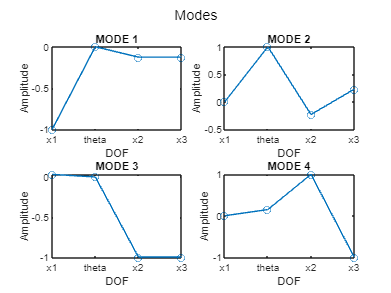


%% Testing Normalisation of Eigen Values, should result in the same value as
tmp         = eigenVector.' * M_matrix_raw * eigenVector;
tmp_row     =  diag(tmp)';
eVec_PHI    = eigenVector ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_matrix_raw * eVec_PHI;
w2_mat      = eVec_PHI.' * K_matrix_raw * eVec_PHI;
w_list = sqrt( double(diag(w2_mat)) );
w_table = array2table( [abs(w_list), abs(w_list/(2*pi))], "VariableNames", {'w_radpersec', 'f_Hz'}  )

my_4dof_sym_list = [x1,  theta,    x2,  x3]
my_4dof_str_list = string(my_4dof_sym_list);

NUM_DOF             =   size(eVec_PHI,1);
MAX_NORM_eVec_PHI   = eVec_PHI ./ repmat(max(abs(eVec_PHI)), NUM_DOF, 1);





mode_table = array2table( MAX_NORM_eVec_PHI, ...
                          "VariableNames",  "MODE_"+[1:4], ...
                          "RowNames"     ,  my_4dof_str_list )

% Convert table to array
mode_array = table2array(mode_table);

% Generate an array for the x-axis based on the number of rows in your table
x = 1:size(mode_array, 1);

% Start a new figure
figure

% Loop through each mode (column in your table)
for i = 1:size(mode_array, 2)
    subplot(2, 2, i);  % Create a 2x2 grid of subplots, this selects the i-th subplot
    plot(x, mode_array(:, i), '-o');  % '-o' specifier is for line with dots

    % Set the x-ticks to be the names of your rows
    xticks(x);
    xticklabels(mode_table.Properties.RowNames);

    % Add legend, title, and labels
    title(['MODE ', num2str(i)]);
    xlabel('DOF');
    ylabel('Amplitude');
end

% Add title to the entire figure
sgtitle('Modes');

% Convert table to array
mode_array = table2array(mode_table);

% Generate an array for the x-axis based on the number of rows in your table
x = 1:size(mode_array, 1);

% Start a new figure
figure 

% Loop through each mode (column in your table)
for i = 1:size(mode_array, 2)
    plot(x, mode_array(:, i), '-o') % '-o' specifier is for line with dots
    hold on  % This is necessary to overlay all the modes on one graph
end

% Set the x-ticks to be the names of your rows
xticks(x);
xticklabels(mode_table.Properties.RowNames);

% Add legend
legend(mode_table.Properties.VariableNames, 'Location', 'best');

% Add title and labels
title('Modes');
xlabel('DOF');
ylabel('Amplitude');



% Assuming your table is already generated as mode_table
% Here is how you plot it:

% First, transform the table to an array for easy manipulation
mode_array = table2array(mode_table);

% Now, let's create a bar graph:
figure 2  % Create new figure
bar(mode_array)
ylabel('Magnitude')
xlabel('Row label')
title('Modes')
legend(mode_table.Properties.VariableNames)  % Add a legend

% if you have many rows, this helps rotate xtick labels for better visibility
xticks(1:numel(mode_table.Properties.RowNames));
xticklabels(mode_table.Properties.RowNames);
xtickangle(45);  % Rotate labels for better visibility




Pull in Experimental Data for comparison

experimental_data = Extract_Half_Car_Rig_Data();
experimental_data


Select Which Data Set you want


Selection = 5;
Lift_position_selection = 'Centre';
Suspension_selection = '1500';
Mass_selection = '0';
index=0;
largest_var=0;
for i=1:length(experimental_data)
    if strcmpi(experimental_data(i).Lift_Position,Lift_position_selection) &...
        strcmpi(experimental_data(i).damping,Suspension_selection) & ...
        strcmpi(experimental_data(i).mass,Mass_selection)
    
        Selected_data_set(i) = experimental_data(i);
        if length(experimental_data(i).rawdata) > largest_var % if multiple data sets prioritise one with more data points
            largest_var =length(experimental_data(i).rawdata);
            index = i;

        end
    end
end

Selected_data_set = Selected_data_set(index);



figure_exp =  figure("name","Experimental");
if Selection ~= 5
    plot(Selected_data_set.cdata.time,Selected_data_set.rawdof(:,Selection+1));
else
    plot(Selected_data_set.cdata.time,Selected_data_set.rawdof(:,2:5));
end
legend("M1\_Pos","M1\_Roll","M2\_Pos","M3\_Pos");
% ylim([-max(abs(Init_param)),max(abs(Init_param))]);
xlim([0,8]);


experimental_init_var = Selected_data_set.init_var;



Running Model

Edit Damping

use_init_var_from_experimental = true;

Damping_Slider = 520;
    M1_Pos = 0.04;
    M1_Roll =0;
    M2_Pos =0;
    M3_Pos =0;



value_list_2 = value_list;
value_list_2(9:10) = Damping_Slider;

M_matrix_subbed = double(subs(M_Mat,sym_list,value_list_2));
C_matrix_subbed = double(subs(C_Mat,sym_list,value_list_2));
K_matrix_subbed = double(subs(K_Mat,sym_list,value_list_2));


if use_init_var_from_experimental

    Init_param = experimental_init_var
else
    Init_param = [M1_Pos,M1_Roll,M2_Pos,M3_Pos];
    Init_param_dot = [0;0;0;0];
end

simOut = sim("x4DOF_Model");

test = simOut.yout{1}.extractTimetable;


figure("name","Simulation");
if Selection ~= 5
    plot(test.Time,test.Data(:,Selection));
else
    plot(test.Time,test.Data);
end
legend("M1\_Pos","M1\_Roll","M2\_Pos","M3\_Pos")
ylim([-max(abs(Init_param)),max(abs(Init_param))]);
xlim(seconds([0,10]));


